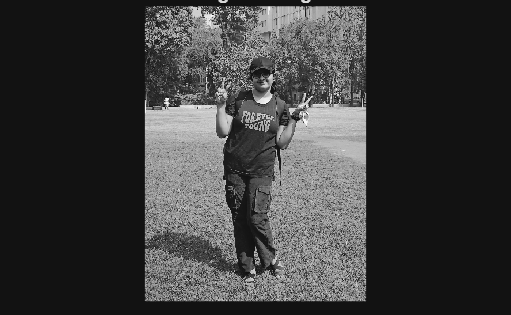

%%% Thresholding %%%

p = rgb2gray(imread('DK.jpg')); 
a = p;
[row, col] = size(a);

% Ask user for threshold value
T = input('Enter value of Threshold :'); 

for i = 1:1:row
    for j = 1:1:col
        if (p(i,j) < T)
            a(i,j) = 0;   % Set to Black
        else
            a(i,j) = 255; % Set to White
        end
    end
end

figure(1);
imshow(p);
title('Original Image');
exportgraphics(gcf, 'T1.png', 'Resolution', 300)

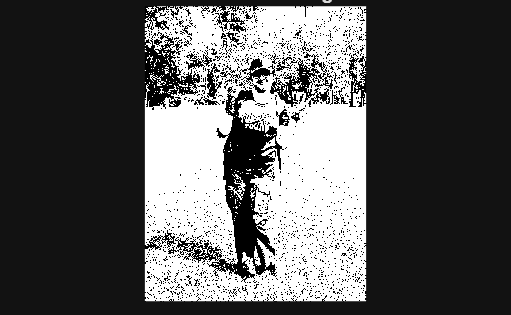


figure(2);
imshow(a);
title('Thresholded Image');
exportgraphics(gcf, 'T2.png', 'Resolution', 300)